# On-board charger (OBC) for electric vehicles

## **Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

## Introduction

An on-board charger (OBC) is a device that charges an Electric Vehicle (EV) directly from the power grid. As the name suggests, the on-board charger is integrated into the vehicle and is carried by the vehicle all the time. Because of this, researchers and OEMs are constantly innovating to ensure that OBCs become lighter and more efficient. A lighter on-board charger increases the range of the EV and a more efficient charger decreases the amount of energy wasted from the grid. This reduces the overall cost per mile for an EV driver.

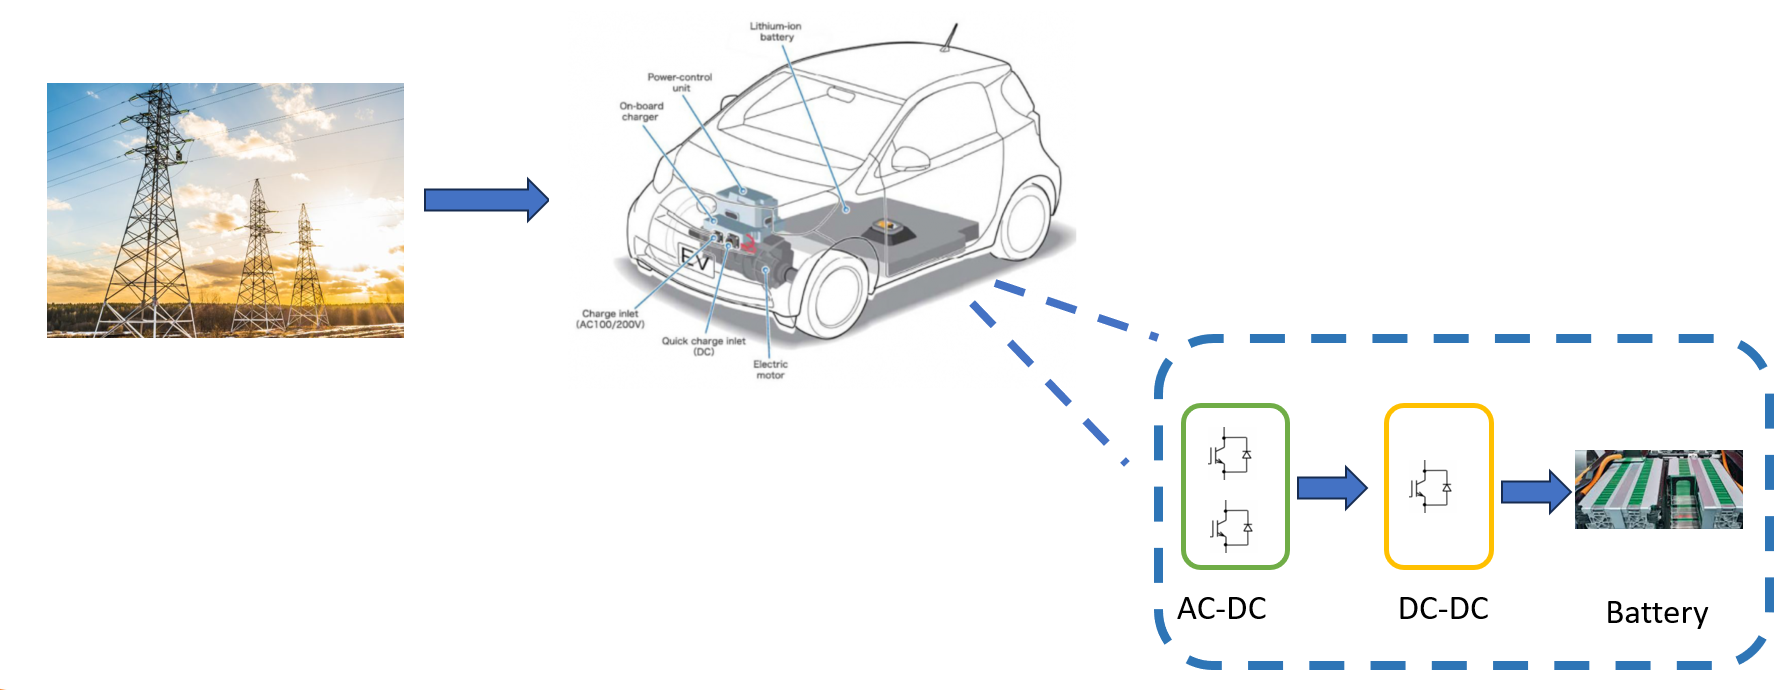

The structure of the Single-phase PV system 

There are four rules a high performance on-board charger should follow:

- The OBC must be able to control the battery charging current and/or voltage

- The OBC must be able to maintain unity power factor when charging the battery (Iq=0)

- For safety, the OBC should be isolated from the grid.

- The OBC should be small and light

## Charging the battery

There are two major stages when charging battery,** constant current** charging and** constant voltage** charging.

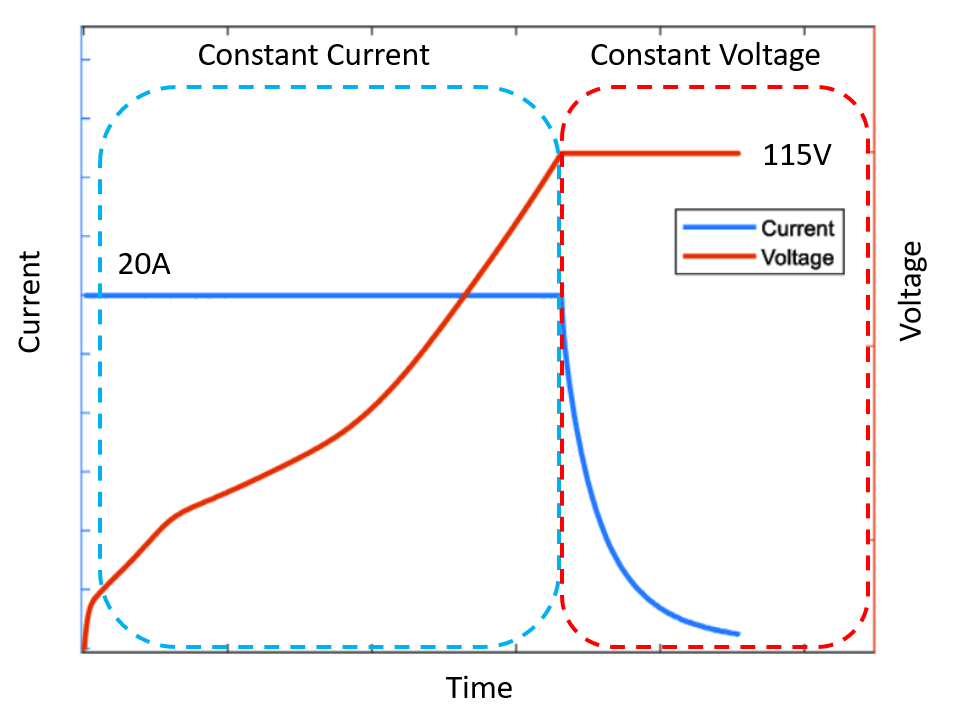

Another important parameter of the battery is the **state of charge** (SOC) which is measure of battery's charge as a percent of full charge. In this model, the SOC is used to show the process and different stages of charging. The SOC is calculated as shown below:


$$\textrm{SOC}=100\left(1-\frac{1}{Q}\int_0^t i\left(t\right)dt\right)$$


## Circuit

## 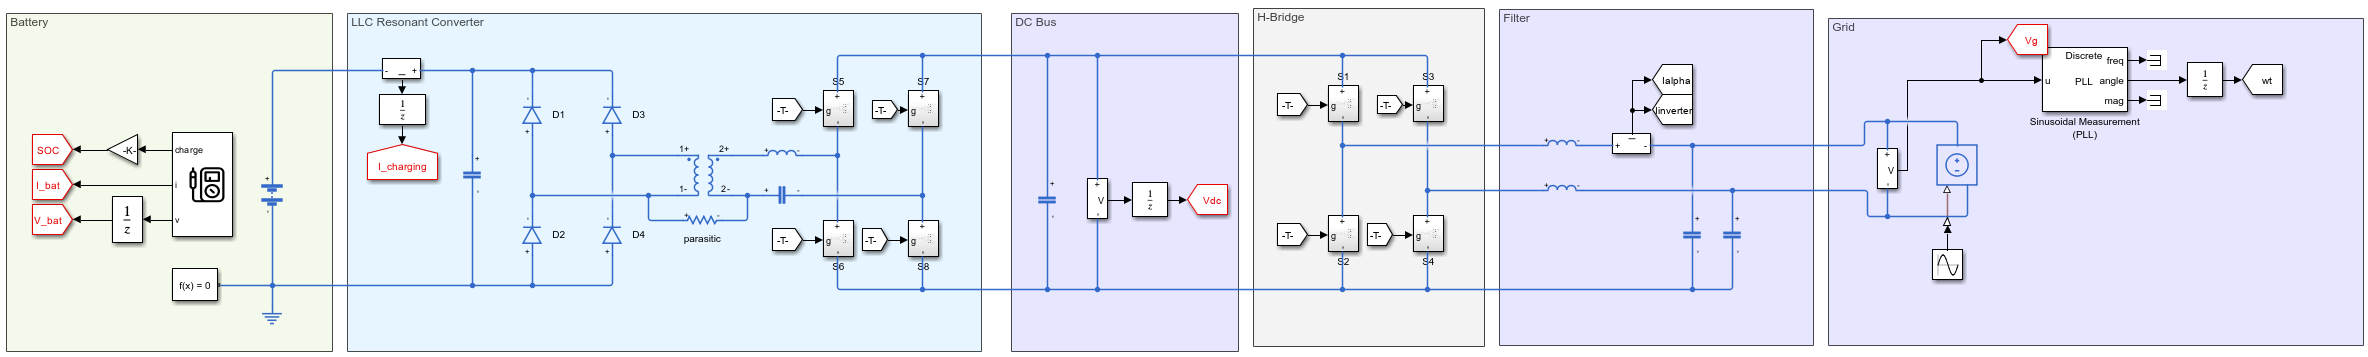

Click the button below to open and explore the model 

 
open_system("model/onboard_SSC_simscape.slx")
if ~exist('Vbat_ref','var')
    Vbat_ref = 115;  
end

Click the **Run** button below. After the simulation is complete (this may take a few minutes) you will get the following four plots below:

- DC output voltage

- Inverter Current

- Battery Voltage & Current

- Battery power

 
runmodel_onboard();

Now, choose from the menu below to learn more about different sections in the model.

switchRectifier("No Selection");

### Connect to the Grid

For simulation purposes, to ensure the **stability** and **quality** of the power grid, the only requirement for the inverter’s AC output is that its **frequency **matches the grid’s frequency and **phase angle**. A Phase-Locked Loop (PLL) strategy is used to measure grid frequency. At this stage, we do not need to examine the internal principles or operation of the PLL. 

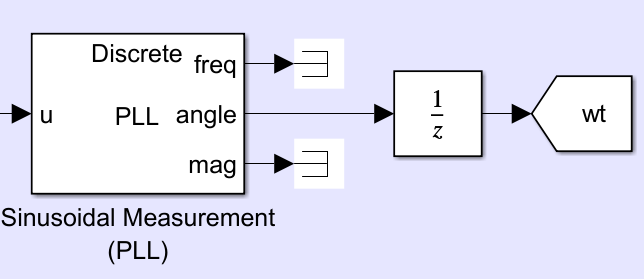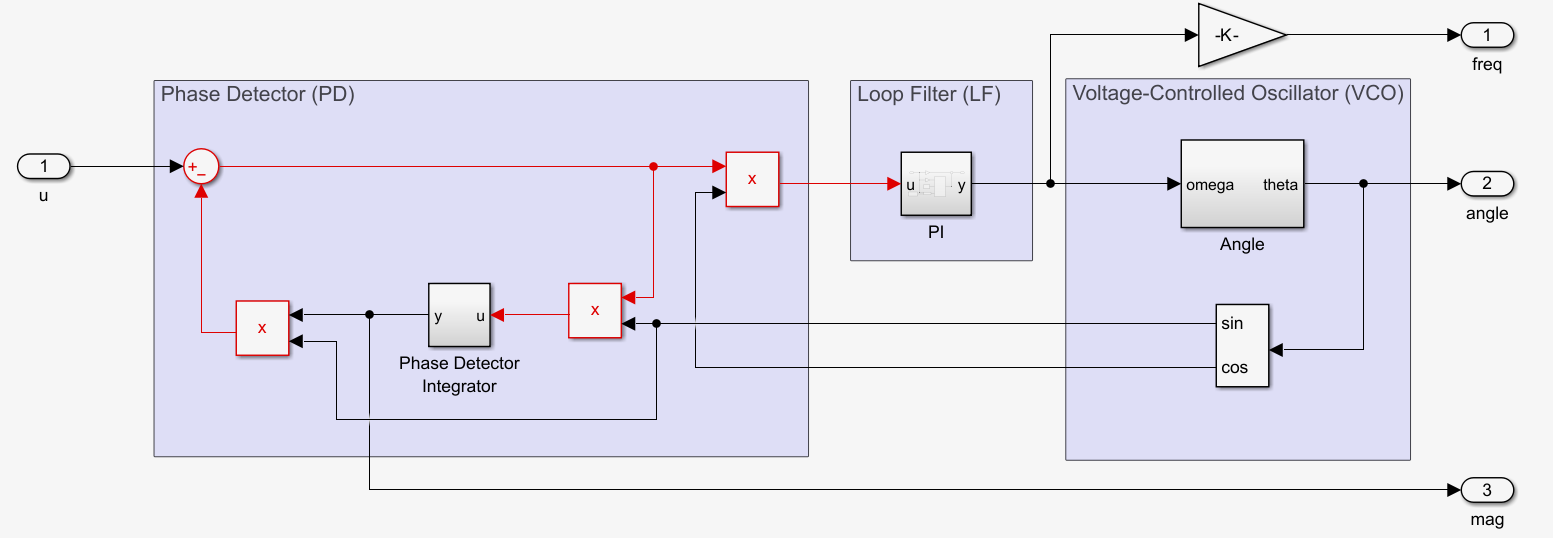

## Control Algorithm

Generally, the control algorithm includes** three** parts: 

- **Charging current/voltage control**

- **Inverter and DC bus control**

- **Second-Order Generalized Integrator (SOGI).**

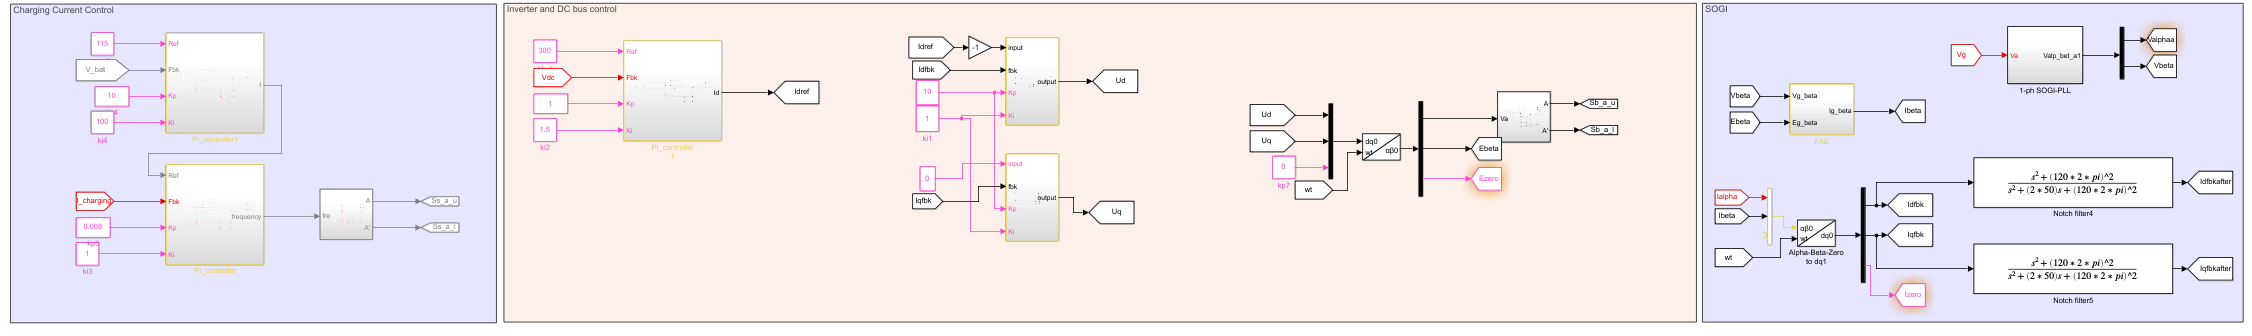

### Charging Current and voltage control

The control algorithm is designed for two stages, **constant current** stage and **constant voltage** stage. 

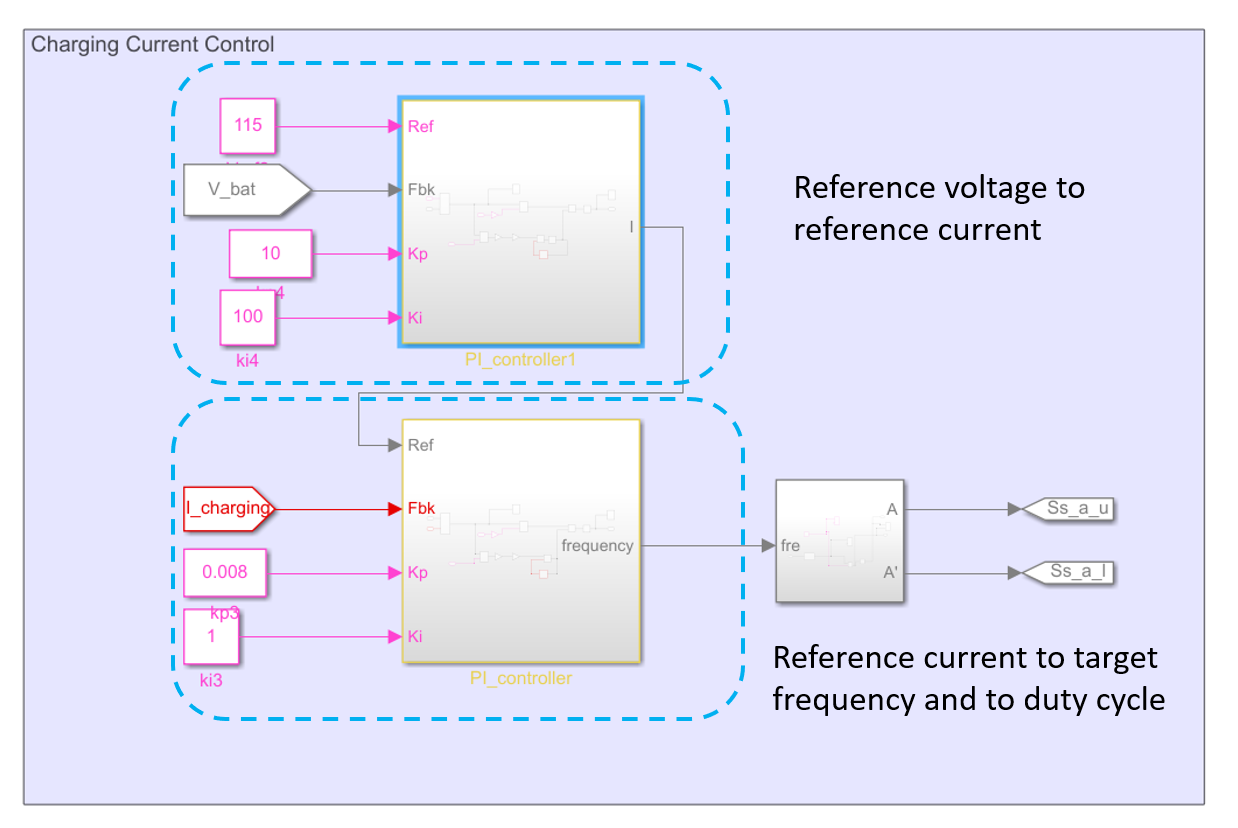

The variable `Vbat_ref` sets the target voltage for the battery charging process. Adjusting this reference affects the charging behavior of the system:

- A **higher **`Vbat_ref` increases the desired battery voltage, leading to higher charging current and output power.

- A **lower **`Vbat_ref` reduces the voltage target, resulting in slower or lighter charging behavior.

Adjust the target voltage using the slider below and click the Run button. After the simulation is complete **(this may take a few minutes)**, see how the initial four responses (DC output voltage, Inverter Current, Battery Voltage & Current, and Battery power) change.

Vbat_ref=150
 
simOut = sim('model/onboard_SSC_simscape.slx', 'ReturnWorkspaceOutputs', 'on');
runmodel_Vbat(simOut);

Now, let's see how the charging stages are set up.

**Constant current charging stage**

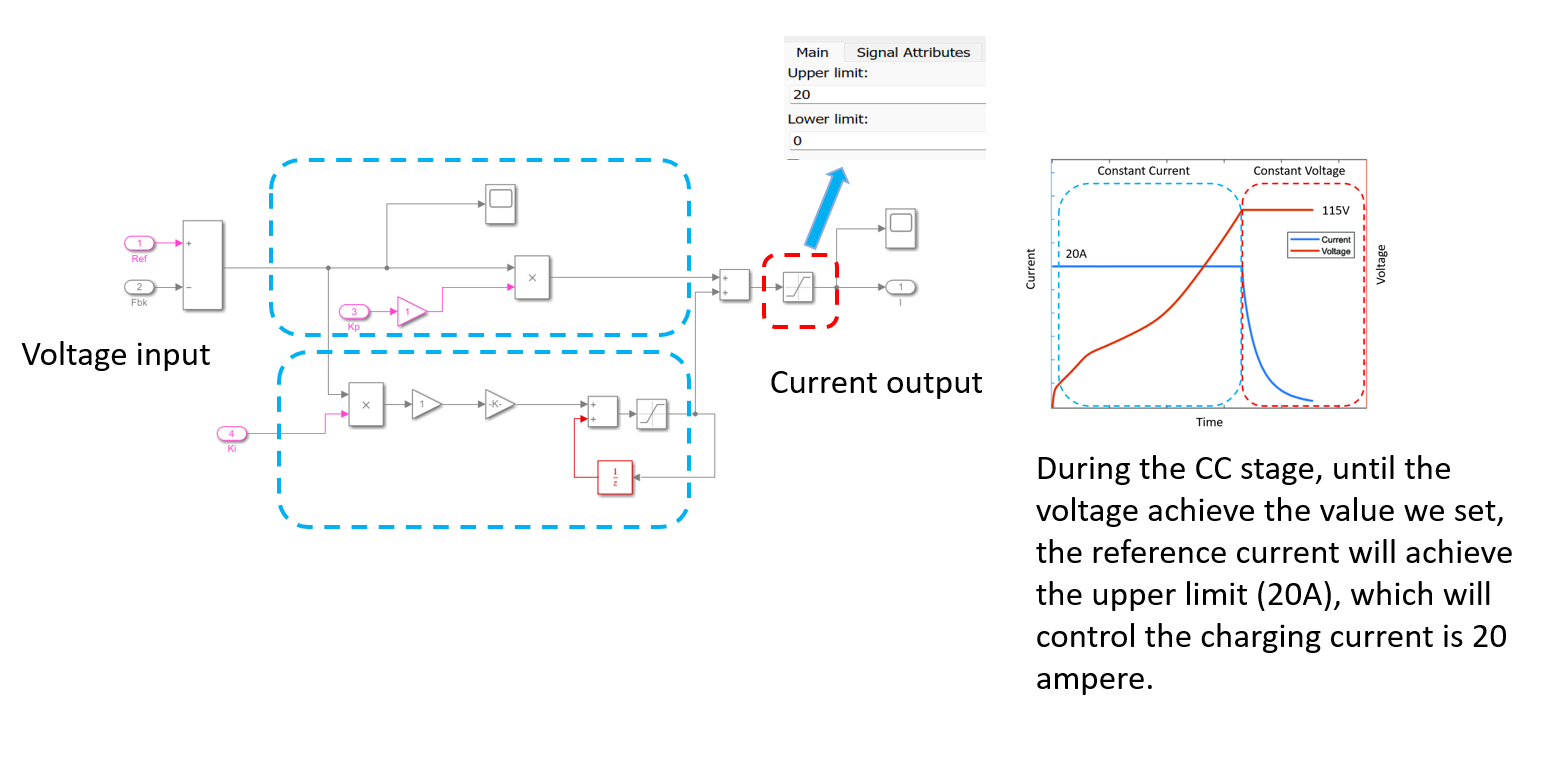

**Constant voltage charging stage**

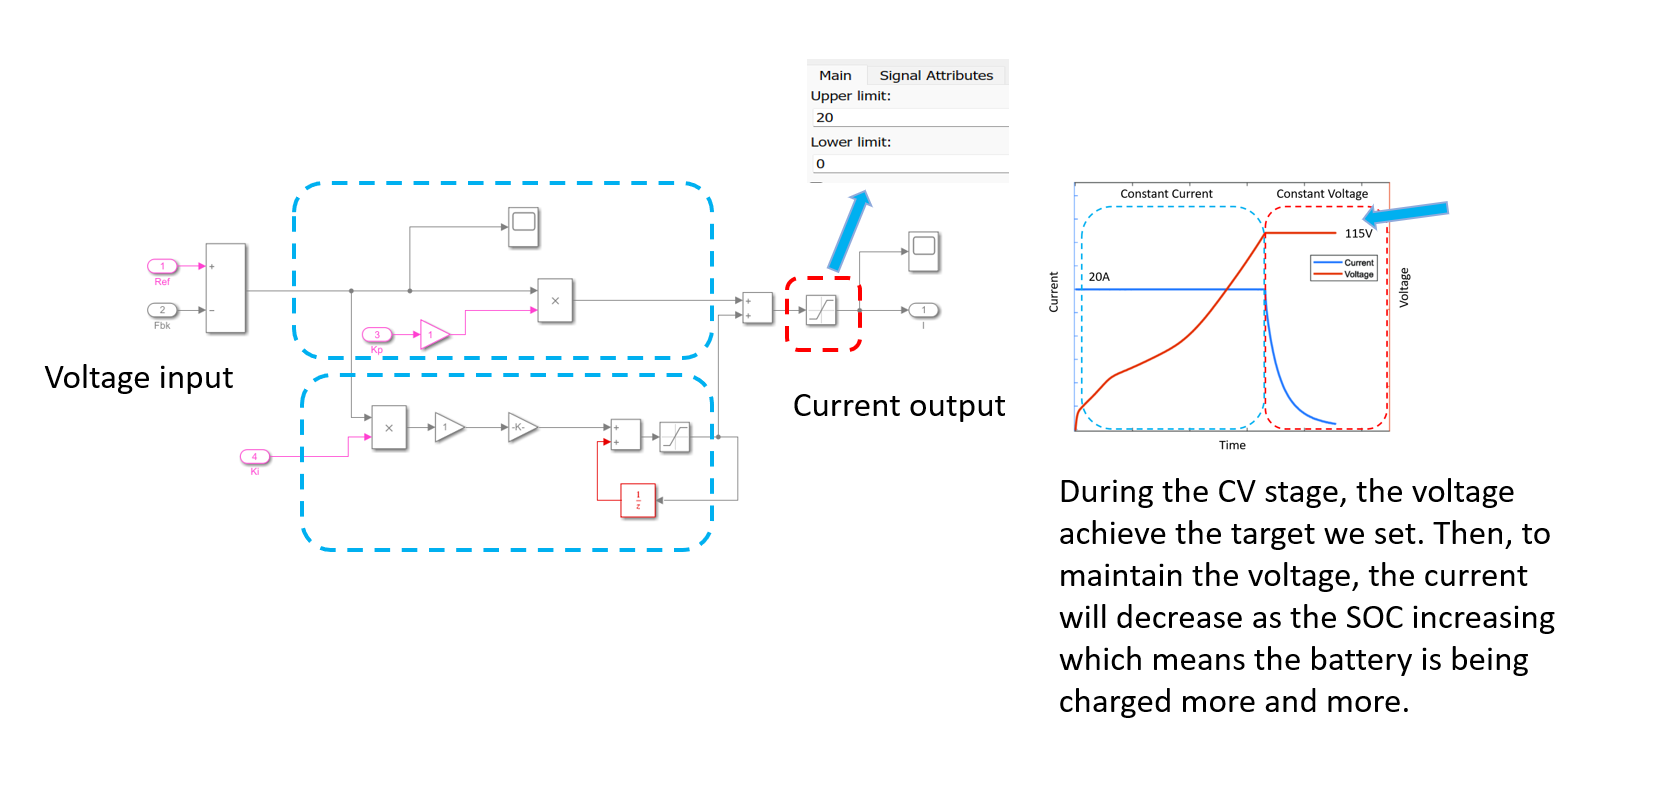

### Inverter and DC Bus Control

Inverter control includes two major parts: **current and voltage controller **and **duty cycle generation **. 

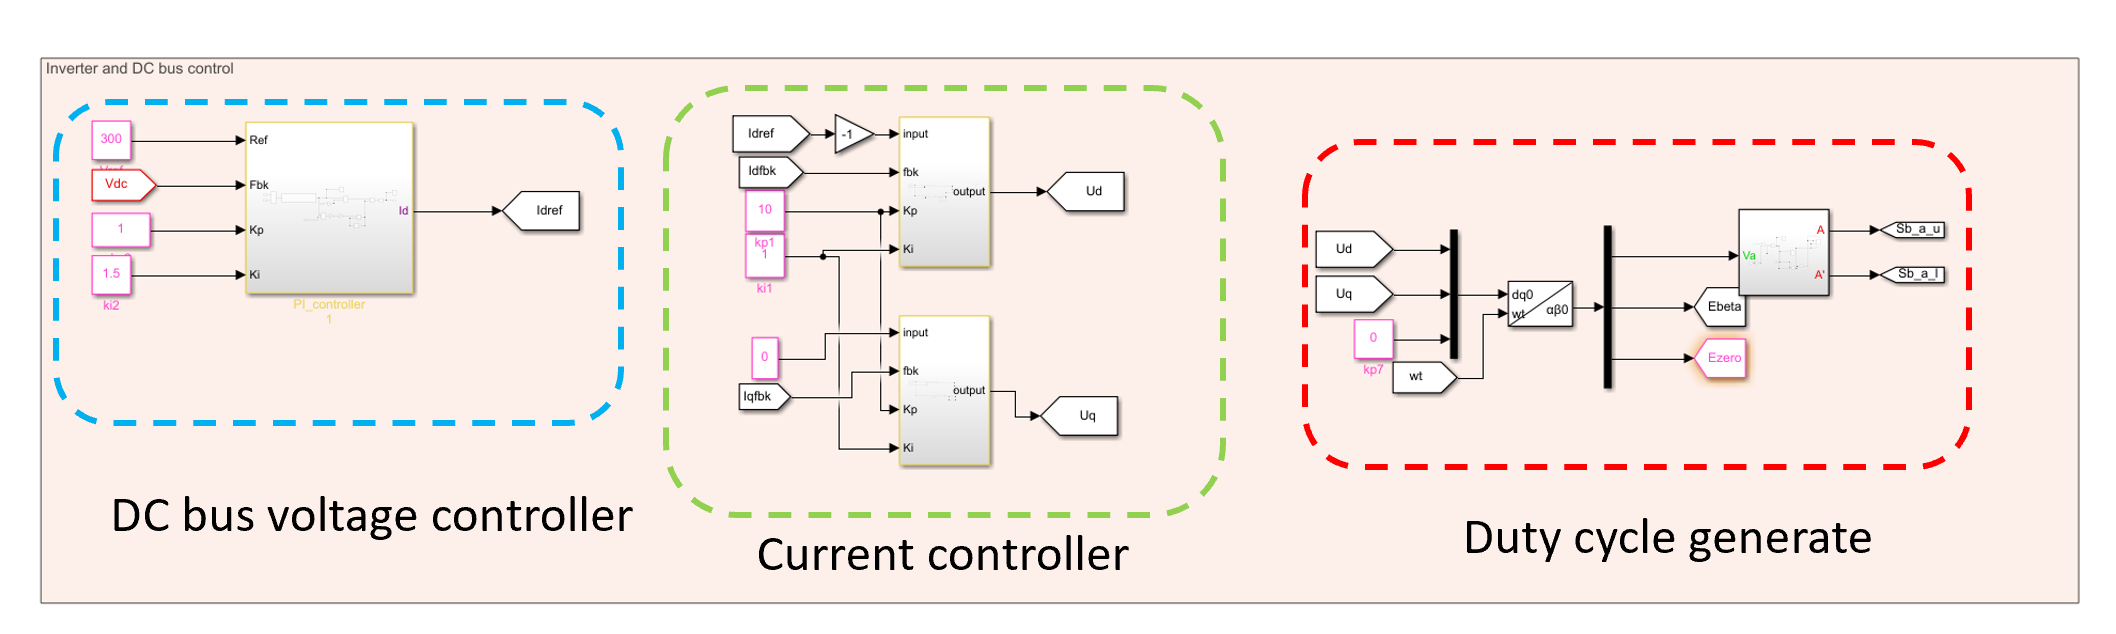

To understand the above three controllers further, select from the following drop down menu.

controller("No Selection")

### SOGI(**Second-Order Generalized Integrator)**

 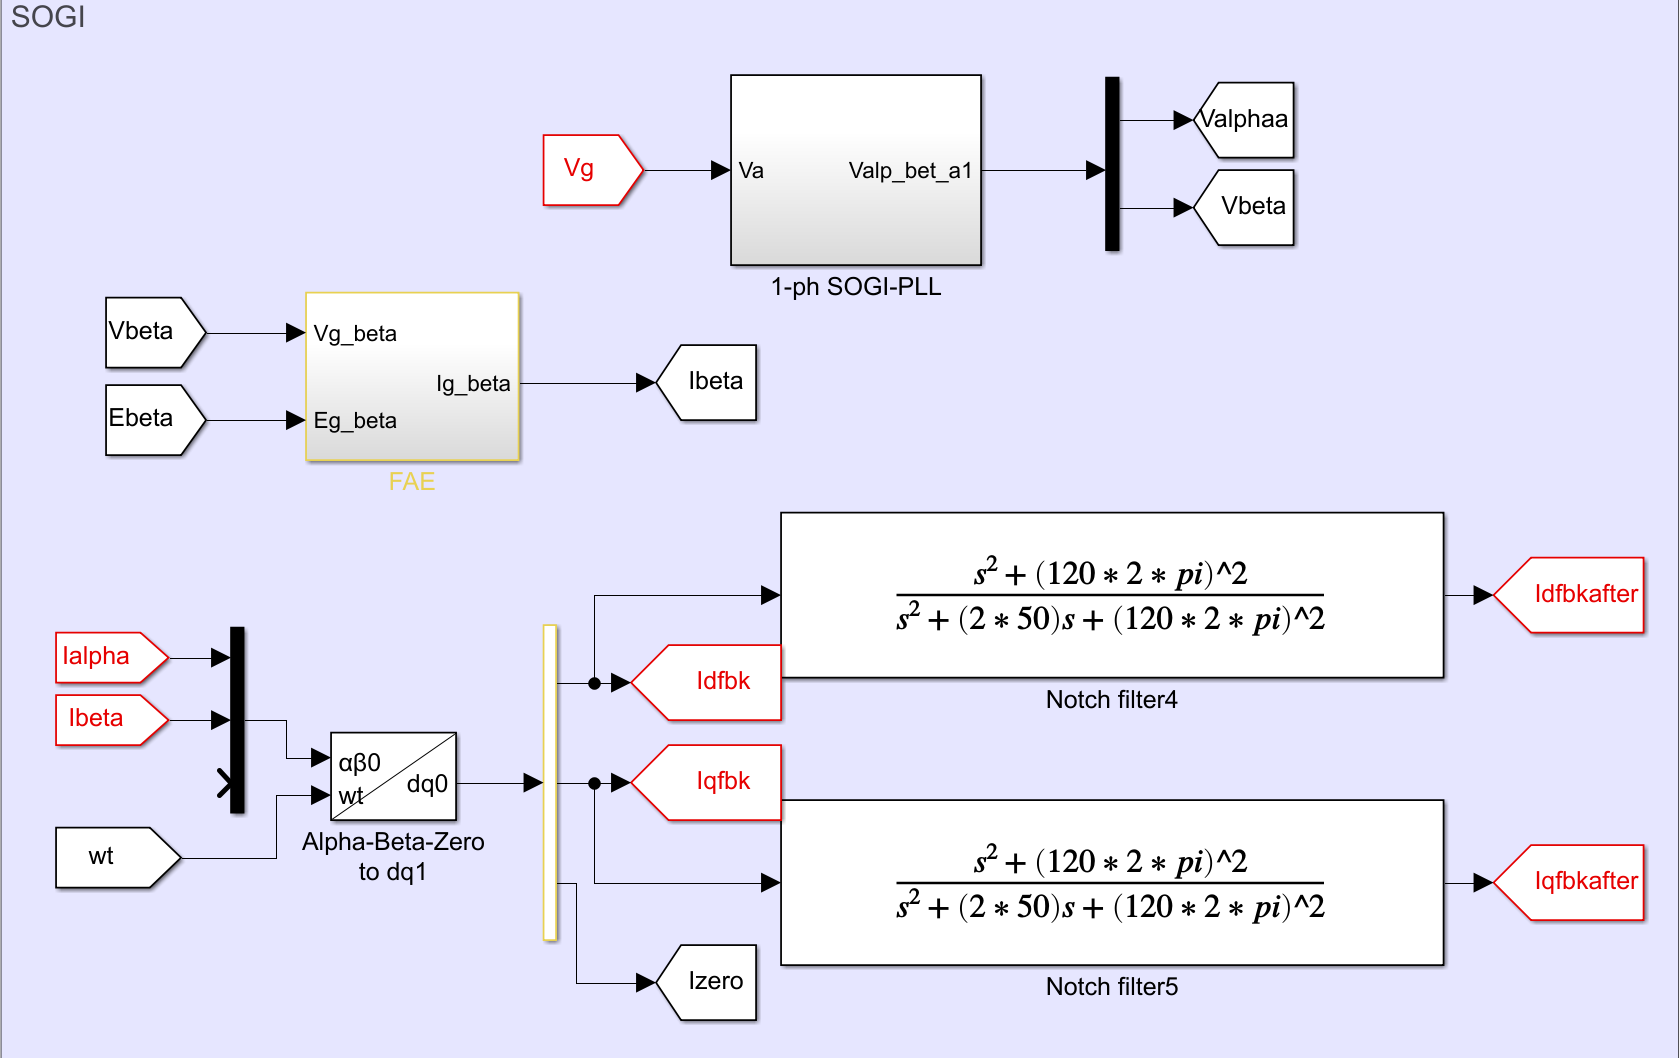

One major difference between the one-phase and three-phase system is that the **alpha,beta-dq transformation** is not complete. Therefore, a virtual beta current will be calculated to make the transformation complete and increase the performance of the current controllers. A SOGI is used to generate the virtual beta voltage. Then, we can use the following equation to calculate the virtual beta current. 

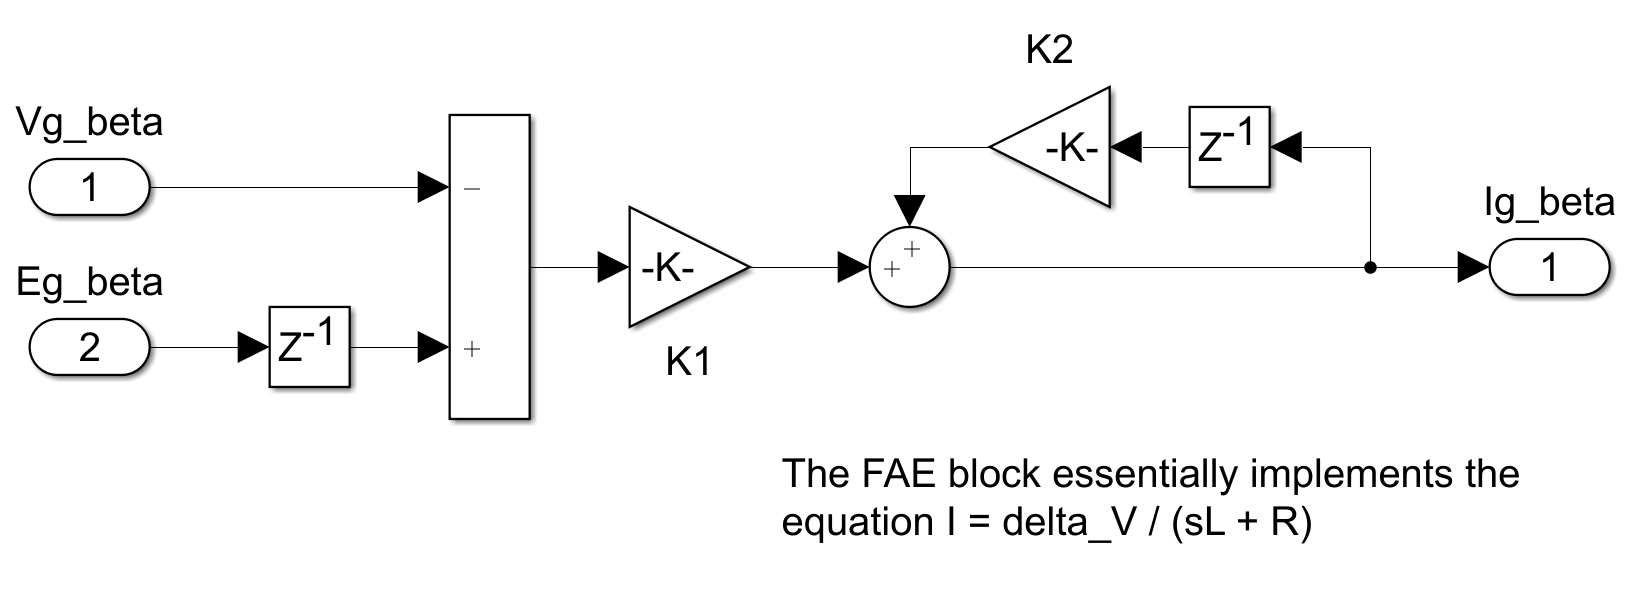

Note that Vg_beta is the voltage generated by the SOGI and the Eg_beta is the voltage calculated from the inverter. 

## Analyzing the Results

Run the model in Simulink, if you haven't done so already. Once the simulation is complete **(this may take a few minutes)**, open the scopes to see the results. 

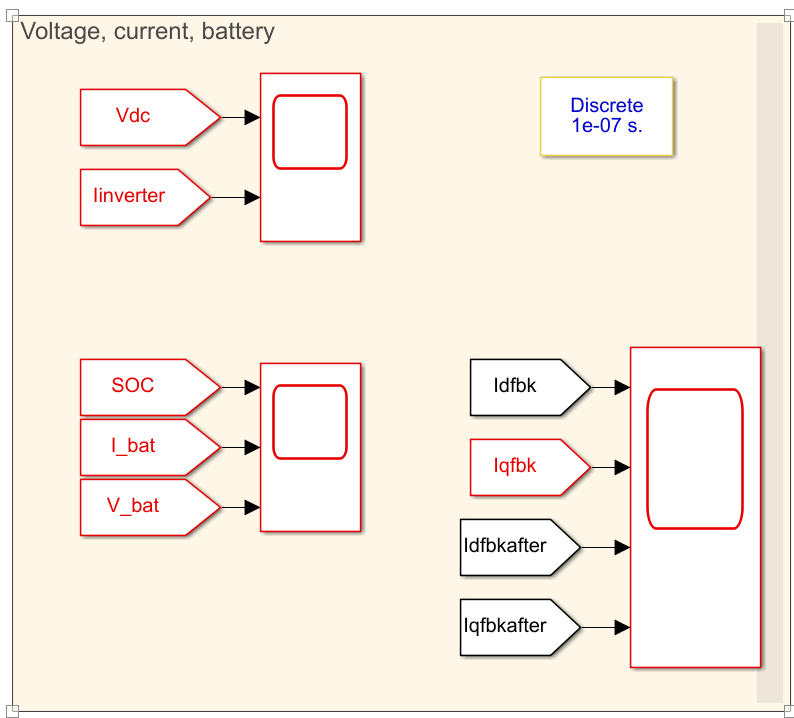

In this model, you are encouraged to change the** initial SOC** of the battery to find the **constant current** and **constant voltage** stages.

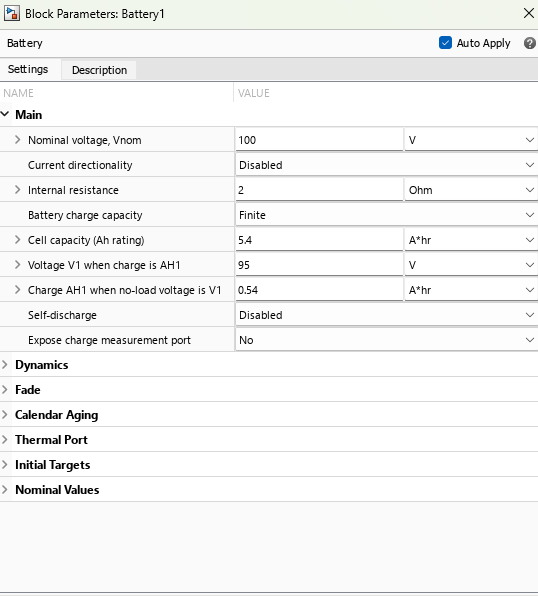

You can also click the following menu to inspect reference simulation results provided for your convenience. **Need to improve plots below**

result("No Selection")

## Conclusion

This live script provides a comprehensive overview of an on-board charger (OBC) system for electric vehicles, emphasizing both conceptual understanding and practical simulation analysis.

Key takeaways include:

- **System Functionality**: The OBC is responsible for converting grid AC to regulated DC to charge the EV battery safely and efficiently. It incorporates both AC-DC and DC-DC conversion stages.

- **Charging Stages**: The battery charging process consists of **constant current (CC)** and **constant voltage (CV)** phases. These are visualized clearly through the current-voltage-time plots and the `Vbat_ref` reference control.

- **Control Strategy**: A cascaded control system is implemented:

- Voltage reference is translated to charging current via outer loop.

- Current is regulated by an inner current controller.

- A **Second-Order Generalized Integrator (SOGI)** is used for reference signal synchronization and virtual β-axis current generation.

- **Simulation-Based Learning**: Interactive simulation with adjustable parameters (e.g., `Vbat_ref`, SOC) helps students explore how voltage reference and control strategies influence battery behavior, Inverter current, and charging power.

- **Visualization**: The four plots (DC bus voltage, Inverter current, battery voltage/current, and battery power) provide clear insights into system dynamics under varying conditions.

This simulation not only demonstrates the principles of power electronics and control theory in EV chargers, but also promotes hands-on learning through MATLAB Live Script interactivity.

## Exercise

 **Exercise 1. What is the correct conversion sequence from power grid to battery?**

warning("on")
exerciseSol1(...
     false, ...
   false);
 

 **Exercise 2. What are the final control target in the battery control?**

warning("on")
exerciseSol2(...
     false, ...
   false,...
  false);
 

 **Exercise 3.What is the resonate frequency of the LLC converter in model?**

warning("on")
exerciseSol3(...
     false, ...
   false,...
   false);
 

function switchRectifier(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "battery" "Grid" "LLC Converter" "Hbridge"])}
end
clf;
if opt == "No Selection"
else
    if opt == "battery"
        rect = imread("Images/battery.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Grid"
        rect = imread("Images/grid.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "LLC Converter"
        rect = imread("Images/LLC.png");
        imshow(rect, 'Interpolation', 'bilinear');
    elseif opt == "Hbridge"
        rect = imread("Images/Hbridge.png");
        imshow(rect, 'Interpolation', 'bilinear');
    end
end
end

function controller(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "DCbus control" "Inverter control" "SPWM"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Inverter control"
        rect = imread("Images/controller.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "SPWM"
        rect = imread("Images/SPWM.png");
        imshow(rect,"Interpolation","bilinear");
    elseif opt == "DCbus control"
        rect = imread("Images/dcbus.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function result(opt)
arguments
    opt (1,1) string {mustBeMember(opt,["No Selection" "Constant Circuit" "Constant Voltage"])}
end
clf;
if opt == "No Selection"
else
    if opt == "Constant Circuit"
        rect = imread("Images/result1.png");
        imshow(rect,'Interpolation',"bilinear");
    elseif opt == "Constant Voltage"
        rect = imread("Images/Result2.png");
        imshow(rect,"Interpolation","bilinear");
    end
end
end

function exerciseSol1(A,B)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        
    end

    if ~any([A B])
        warning("Please select one that apply!")
    elseif A+B > 1
        warning("Please select only one option")
    elseif A
        disp("Correct!")
    else 
        warning("Incorrect. Please review the circuit section again")
    end
end

function exerciseSol2(A,B,C)
  
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
        
    end

    if ~any([A B C])
        warning("Please select an answer!")
    elseif A+B+C > 1
        warning("Please select only one option")
    elseif B
        disp("Correct!")
    else 
        warning("Incorrect. Please review the control section again")
    end
end

function exerciseSol3(A,B,C)
 
    arguments
        A (1,1) logical
        B (1,1) logical
        C (1,1) logical
    end

    if ~any([A B C])
        warning("Please select an answer!")
    elseif A+B+C > 1
        warning("Please select only one option")    
    elseif C
        disp("Correct!")
    else 
        warning("Incorrect")
    end
end

function showpic1(A)

    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/CC.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end
function showpic2(A)
   
    arguments
        A (1,1) logical   
    end
    clf;
    if A
        rect = imread("Images/CV.png");
        imshow(rect,'Interpolation',"bilinear");
    else 
    end
end

function runmodel_onboard()
    warning('off', 'all'); 
    sim('model/onboard_SSC_simscape.slx');

    try
        N = min([length(tout), length(Vdc), length(Iinverter), length(V_bat), length(I_bat)]);
        time      = tout(1:N);
        vdc_val   = Vdc(1:N);
        iinv_val  = Iinverter(1:N);
        vbat_val  = V_bat(1:N);
        ibat_val  = -I_bat(1:N);  
        power_val = vdc_val .* ibat_val;

        figure('Position', [100, 100, 1000, 800]);

 
        subplot(2,2,1);
        plot(time, vdc_val, 'b', 'LineWidth', 1.5);
        title('DC Output Voltage'); 
        xlabel('Time (s)'); ylabel('V_{dc} (V)'); grid on;

        subplot(2,2,2);
        plot(time, iinv_val, 'r', 'LineWidth', 1.5);
        xlim([0.3, 0.5]);
        title('Inverter Current'); 
        xlabel('Time (s)'); ylabel('I_{inverter} (A)'); grid on;

        subplot(2,2,3);
        plot(time, vbat_val, 'm', time, ibat_val, 'g', 'LineWidth', 1.5);
        title('Battery Voltage & Current');
        xlabel('Time (s)'); ylabel('Value'); 
        legend('V_{bat}', 'I_{bat}'); grid on;

        subplot(2,2,4);
        plot(time, power_val, 'k', 'LineWidth', 1.5);
        title('Battery Power'); 
        xlabel('Time (s)'); ylabel('P_{out} (W)'); grid on;

    catch ME
        disp('❌ Error occurred during plotting:');
        disp(ME.message);
    end
end

function runmodel_Vbat(simOut)
    warning('off', 'all');

    try

        time      = simOut.tout;
        vdc_val   = simOut.Vdc;
        iinv_val  = simOut.Iinverter;
        vbat_val  = simOut.V_bat;
        ibat_val  = -simOut.I_bat;

     
        N = min([length(time), length(vdc_val), length(iinv_val), length(vbat_val), length(ibat_val)]);
        time      = time(1:N);
        vdc_val   = vdc_val(1:N);
        iinv_val  = iinv_val(1:N);
        vbat_val  = vbat_val(1:N);
        ibat_val  = ibat_val(1:N);
        power_val = vdc_val .* ibat_val;


        figure('Position', [100, 100, 1000, 800]);

        subplot(2,2,1);
        plot(time, vdc_val, 'b', 'LineWidth', 1.5);
        title('DC Output Voltage'); xlabel('Time (s)'); ylabel('V_{dc} (V)'); grid on;

        subplot(2,2,2);
        plot(time, iinv_val, 'r', 'LineWidth', 1.5);
        xlim([0.3, 0.5]);
        title('Inverter Current'); xlabel('Time (s)'); ylabel('I_{inverter} (A)'); grid on;

        subplot(2,2,3);
        plot(time, vbat_val, 'm', time, ibat_val, 'g', 'LineWidth', 1.5);
        title('Battery Voltage & Current');
        xlabel('Time (s)'); ylabel('Value'); legend('V_{bat}', 'I_{bat}'); grid on;

        subplot(2,2,4);
        plot(time, power_val, 'k', 'LineWidth', 1.5);
        title('Battery Power'); xlabel('Time (s)'); ylabel('P (W)'); grid on;

    catch ME
        disp('❌ Error occurred during plotting:');
        disp(ME.message);
    end
end
